# LQR Controller Design for Inverse Pendulum Control

clc; clear;

Ts = 0.01;
syms theta theta_dot alpha alpha_dot real
syms theta_ddot alpha_ddot real
syms Vm real
R_m = 8.4;
K_m = 0.042;
M_r = 0.095;
L_r = 0.085;
J_r = 5.72e-5;
D_r = 0.0015;
M_p = 0.024;
L_p = 0.129;
J_p = 3.33e-5;
D_p = 0.0005;
g = 9.81;

## Linearization of the Nonlinear Model

func(1) = (M_p*L_r^2+1/4*M_p*L_p^2*(cos(alpha))^2+J_r)*theta_ddot + 1/2*M_p*L_p*L_r*cos(alpha)*alpha_ddot + 1/2*M_p*L_p^2*sin(alpha)*cos(alpha)*theta_dot*alpha_dot-1/2*M_p*L_p*L_r*sin(alpha)*alpha_dot^2 - K_m*(Vm - K_m*theta_dot)/R_m + D_r*theta_dot;
func(2) = 1/2*M_p*L_p*L_r*cos(alpha)*theta_ddot+(J_p+1/4*M_p*L_p^2)*alpha_ddot-1/4*M_p*L_p^2*cos(alpha)*sin(alpha)*theta_dot^2+1/2*M_p*L_p*g*sin(alpha) + D_p*alpha_dot;
func = subs(func, [alpha, alpha_dot], [alpha-pi, alpha_dot]);
[theta_ddot, alpha_ddot] = solve(func == [0;0], [theta_ddot, alpha_ddot]);

theta_ddot = simplify(theta_ddot);
matlabFunction(theta_ddot, 'File', 'get_theta_ddot', 'vars', {theta theta_dot alpha alpha_dot, Vm});

alpha_ddot = simplify(alpha_ddot);
matlabFunction(alpha_ddot, 'File', 'get_alpha_ddot', 'vars', {theta theta_dot alpha alpha_dot, Vm});

x = [theta; theta_dot; alpha; alpha_dot];
x_dot = [theta_dot; theta_ddot; alpha_dot; alpha_ddot];

## Linear State Space Model

% 4 states, 1 control
num_state = 4;
num_ctl = 1;

A = double(subs(jacobian(x_dot, x), [theta; theta_dot; alpha; alpha_dot], [0;0;0;0]));
B = double(subs(jacobian(x_dot, Vm), [theta; theta_dot; alpha; alpha_dot], [0;0;0;0]));
C = [1,0,0,0; 0,0,1,0];
D = [0;0];
sys = ss(A,B,C,D);
size(sys)

State-space model with 2 outputs, 1 inputs, and 4 states.


pole(sys)

ans =          0
  -20.0802
   -4.7809
   10.1369


## LQR

Q = diag([10 0 100 0]); %stability penalty, higher Q, higher track quality 12 times
R = 1e0*eye(num_ctl); %control usage penalty, higher R, lower control usage

K_lqr = lqr(A, B, Q, R);
eig(A-B*K_lqr)

ans =  -17.1172 + 6.1697i
 -17.1172 - 6.1697i
  -4.2813 + 2.9749i
  -4.2813 - 2.9749i


L_lqr = sys*K_lqr;
size(L_lqr)

State-space model with 2 outputs, 4 inputs, and 4 states.


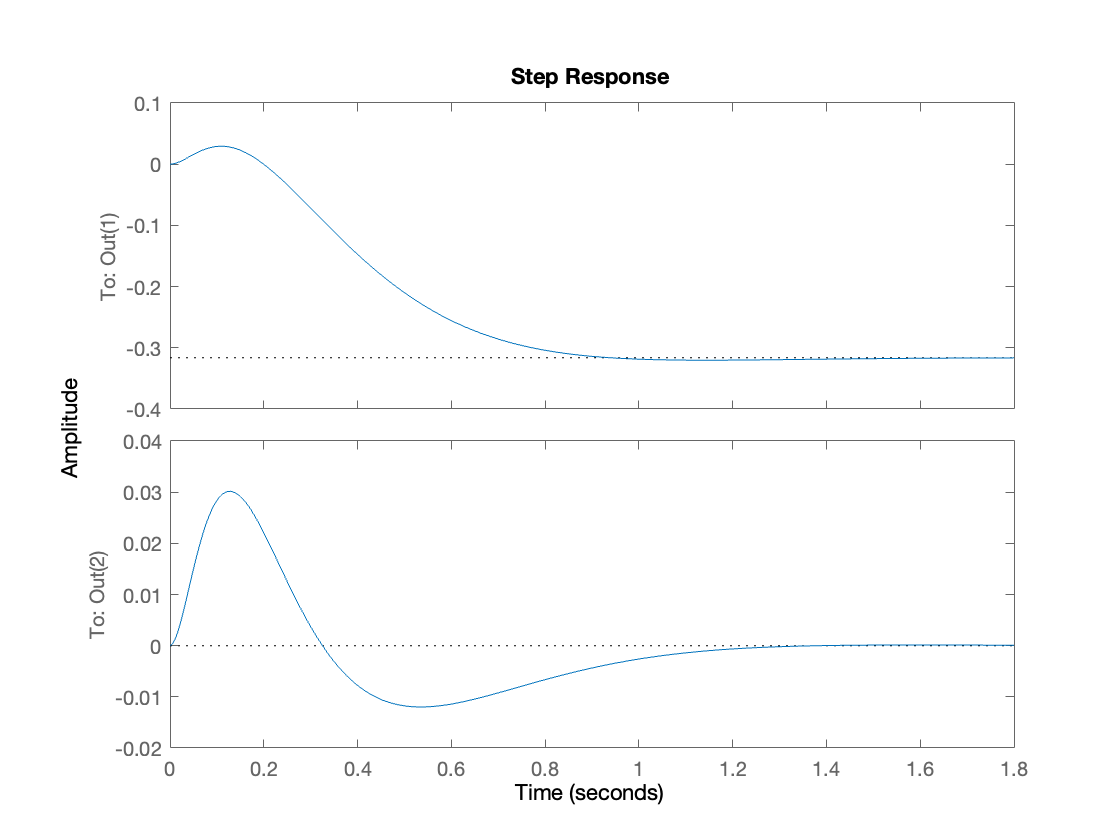

sys_lqr = ss(A-B*K_lqr, B, C, D);
step(sys_lqr)

## LQR with Luenberger w/ Pole Placement

placed_poles = [-50 -51 -52 -53];
L_luen = place(A', C', placed_poles)';
obs_luen = ss(A-L_luen*C,[B L_luen], eye(4), []);
eig(A-L_luen*C)

ans =   -50.0000
  -53.0000
  -51.0000
  -52.0000


## LQR with Kalman Filter

sys.InputName = {'un'};
sys.OutputName = {'y1','y2'};
Sum = sumblk('un = u + w');
sys_kf = connect(sys, Sum, {'u','w'}, {'y1','y2'});
Q = 1e4; %we don't trust the model
R = [1 0; 0 1];
[~,Lkf,Pkf] = kalman(sys_kf, Q, R, 0);
obs_kf = ss(A-Lkf*C,[B Lkf], eye(4), []);
eig(A-Lkf*C)

ans =  -43.0713 +40.6440i
 -43.0713 -40.6440i
  -8.4365 + 3.1559i
  -8.4365 - 3.1559i
